clc, clear all
syms psi q1 q2 q3 q4 q5 l1 l2 l3 l4 l5 a b c ul um un xu yu zu

## Simulacion

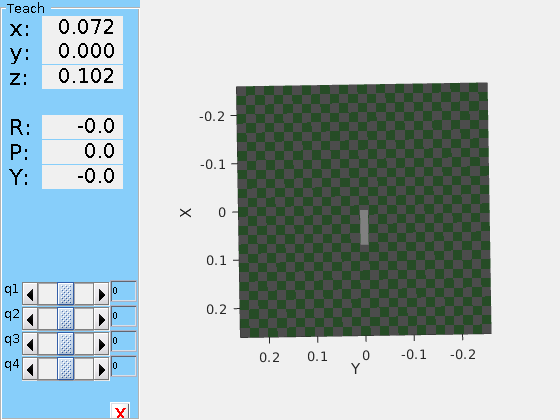

%L1 = -1; L2 = 1; L3 = 1; L4 = 1; L5 = 1;
L1 = -0.042; 
L2 = 0.072; 
L3 = 0.072;
L4 = 0.072;
L5 = 0.045;
% Primer Brazo
Lx(1) = Link([0 L1 0 -pi/2]); 
Lx(2) = Link([0 0 L2 0 ]);
Lx(3) = Link([0 0 0 pi/2 ]);
Lx(4) = Link([0 L3+L4 0 0]);

robot = SerialLink(Lx);
robot.name = 'RRR';
robot.teach;

## Denavit-Hartembet Modelo Cinematico


H01 = D_H(q1,-l1,0,-pi/2)

$$H01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & -l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12 = D_H(q2,0,l2,0)

$$H12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23 = D_H(q3,0,0,pi/2)

$$H23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & 0\\ \sin\left(q_{3}\right) & 0 & -\cos\left(q_{3}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H34 = D_H(q4,l3+l4,0,0)

$$H34 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 0\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & l_{3}+l_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H05 = H01*H12*H23*H34

$$H05 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\sigma_{3}-\sin\left(q_{1}\right)\,\sin\left(q_{4}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{4}\right)\,\sigma_{3} & \sigma_{4} & \left(l_{3}+l_{4}\right)\,\sigma_{4}+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\sigma_{1} & \cos\left(q_{1}\right)\,\cos\left(q_{4}\right)+\sin\left(q_{4}\right)\,\sigma_{1} & \sigma_{2} & \left(l_{3}+l_{4}\right)\,\sigma_{2}+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\cos\left(q_{4}\right)\,\sigma_{6} & \sin\left(q_{4}\right)\,\sigma_{6} & \sigma_{5} & \left(l_{3}+l_{4}\right)\,\sigma_{5}-l_{1}-l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{5}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) \end{array}$$


hx_1 = simplify(H05(1,4))

$$hx\_1 = \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)$$

hy_1 = simplify(H05(2,4))

$$hy\_1 = \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)$$

hz_1 = simplify(H05(3,4))

$$hz\_1 = \cos\left(q_{2}+q_{3}\right)\,\left(l_{3}+l_{4}\right)-l_{1}-l_{2}\,\sin\left(q_{2}\right)$$


hx = a*cos(psi)- b*sin(psi) + hx_1;
hy = a*sin(psi)+ b*cos(psi) + hy_1;
hz = c + hz_1;
q4 = q4;


J=jacobian([hx,hy,hz,q4],[q1,q2,q3,q4]);

J=simplify(J)

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \sigma_{2}-l_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{2} & 0\\ \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & \sigma_{1}-l_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{1} & 0\\ 0 & -\sigma_{3}-l_{2}\,\cos\left(q_{2}\right) & -\sigma_{3} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)\\ \sigma_{2}=\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(l_{3}+l_{4}\right)\\ \sigma_{3}=\sin\left(q_{2}+q_{3}\right)\,\left(l_{3}+l_{4}\right) \end{array}$$

## +UAV